# Road Conversion Algorithm

This algorithm is mainly in "map_v1/map_extend_v1.m".

These two mat file is loaded in "map_v1/map_extend_v1.m" If there is another version of the extended map, just change the "map_v1.mat" to another one.

First, load the data file which include the coordinate of several points of each road section.

load map_v1.mat;

This data file can be changed and saved from drivingScenarioDesigner, which is used to extend the map under OPENDrive format.

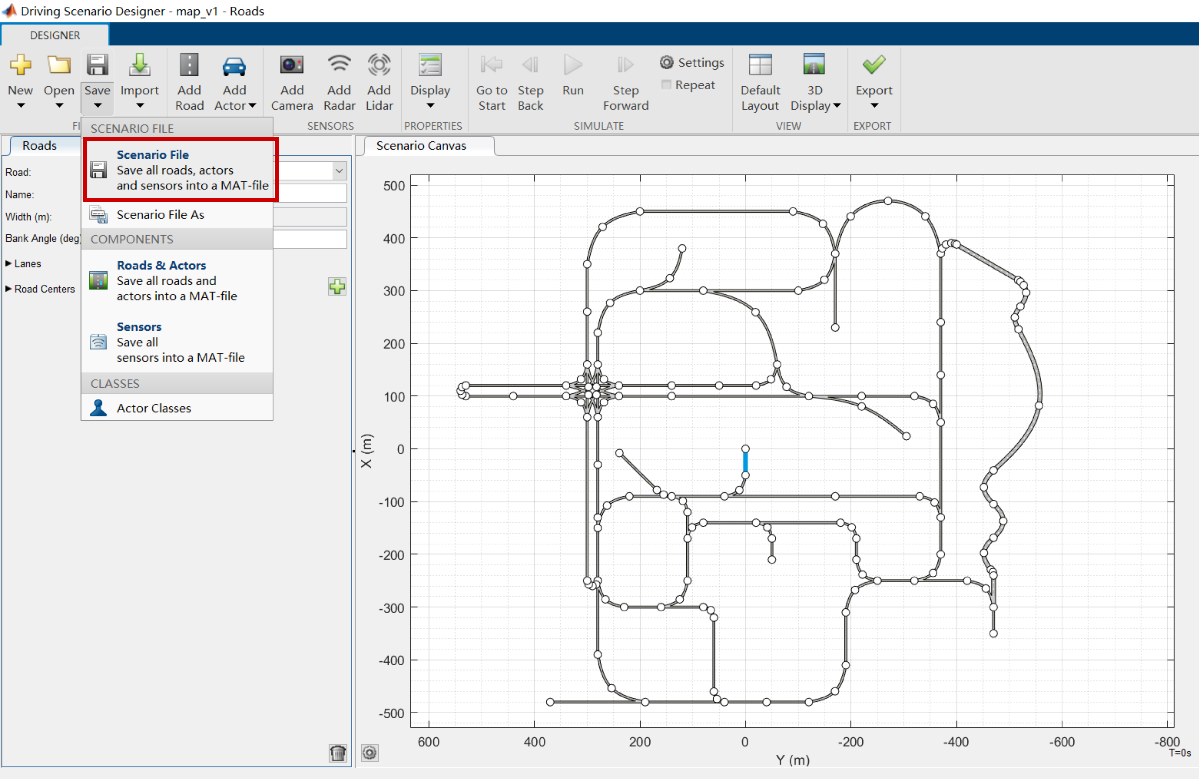

Then load the data file from original map, which is got from "Load Data/load_mobatkent.m". Because when the map is converted from drivingScenarioDesgner, the sequence of the points is totally different,  we need to make it into right sequence according to the original map.

load waypoints_origin.mat;

Initialize the arrary for road information which is the same form of "Load Data/load_Mobatkent.m".

waypoints_new = [];% waypoints of extended map before oder the sequence
connections_circle = [];
connections_translation = [];
waypoints = [];% waypoints of extended map with the right order
WP_from_app = []; % waypoints got from drivingScenarioDesigner
Route_LaneNumber = []; % [Route_id, LaneNumber]

 Next, according to the information of above two loaded data file,  the algorithm transfer points coordinate to the information that we need, the detailed comment please find in "map_v1/map_extend_v1.m" 

There are two help functions in the folder "map_v1", which are used in "map_extend_v1.m" :

"Circle_center.m": calculate the circle center of the curved road section.

"Order_sequence.m": put the points in extended map into the same order of the original map.

If you just run "map_v1/map_extend_v1.m", there are four output arrays,:

When you make some changes, don't forget to check if the above output is correct.

The final output of the "map_extend_v1.m" is the form shows below:

waypoints = [x,0,-y];
connections_translation = [startpoint, endpoint, speed];% the straight road section in the map
connections_circle = [startpoint, endpoint, radian, circleCenter_x,0,-circleCenter_y, speed];% the curved road section in the map
Route_LaneNumber = [Route_id, laneNumber] % lane number of the corresponding route

Next, just add the below line in "Load Data\load_Mobatkent_from_opendrive.m"

run map_extend_v1.m

Next, load extended map in load map section in "Scripts/prepare_simulator.m" instead of the orignal one.

%% Load the Map
switch mapSelection  
    case 'Mobatkent'
        %load_Mobatkent();
        load_Mobatkent_from_opendrive();%load extended map
    case 'Highway'
        open_system('Platoon_Event')
        return
    
    case 'Crossmap'
        load_Crossmap();             
end

Finally, run "prepare_simulator.m", you can get the map in the simulation.